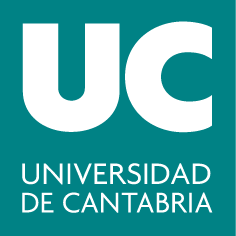

#### ***Grado de Tecnologías de Telecomunicacion***

## **G282: Álgebra y Geometria**

# **Práctica 1: Introducción a MATLAB**

*Departamento de Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Familiarizarse con el entorno MATLAB

- Crear vectores y matrices

- Calcular determinantes 

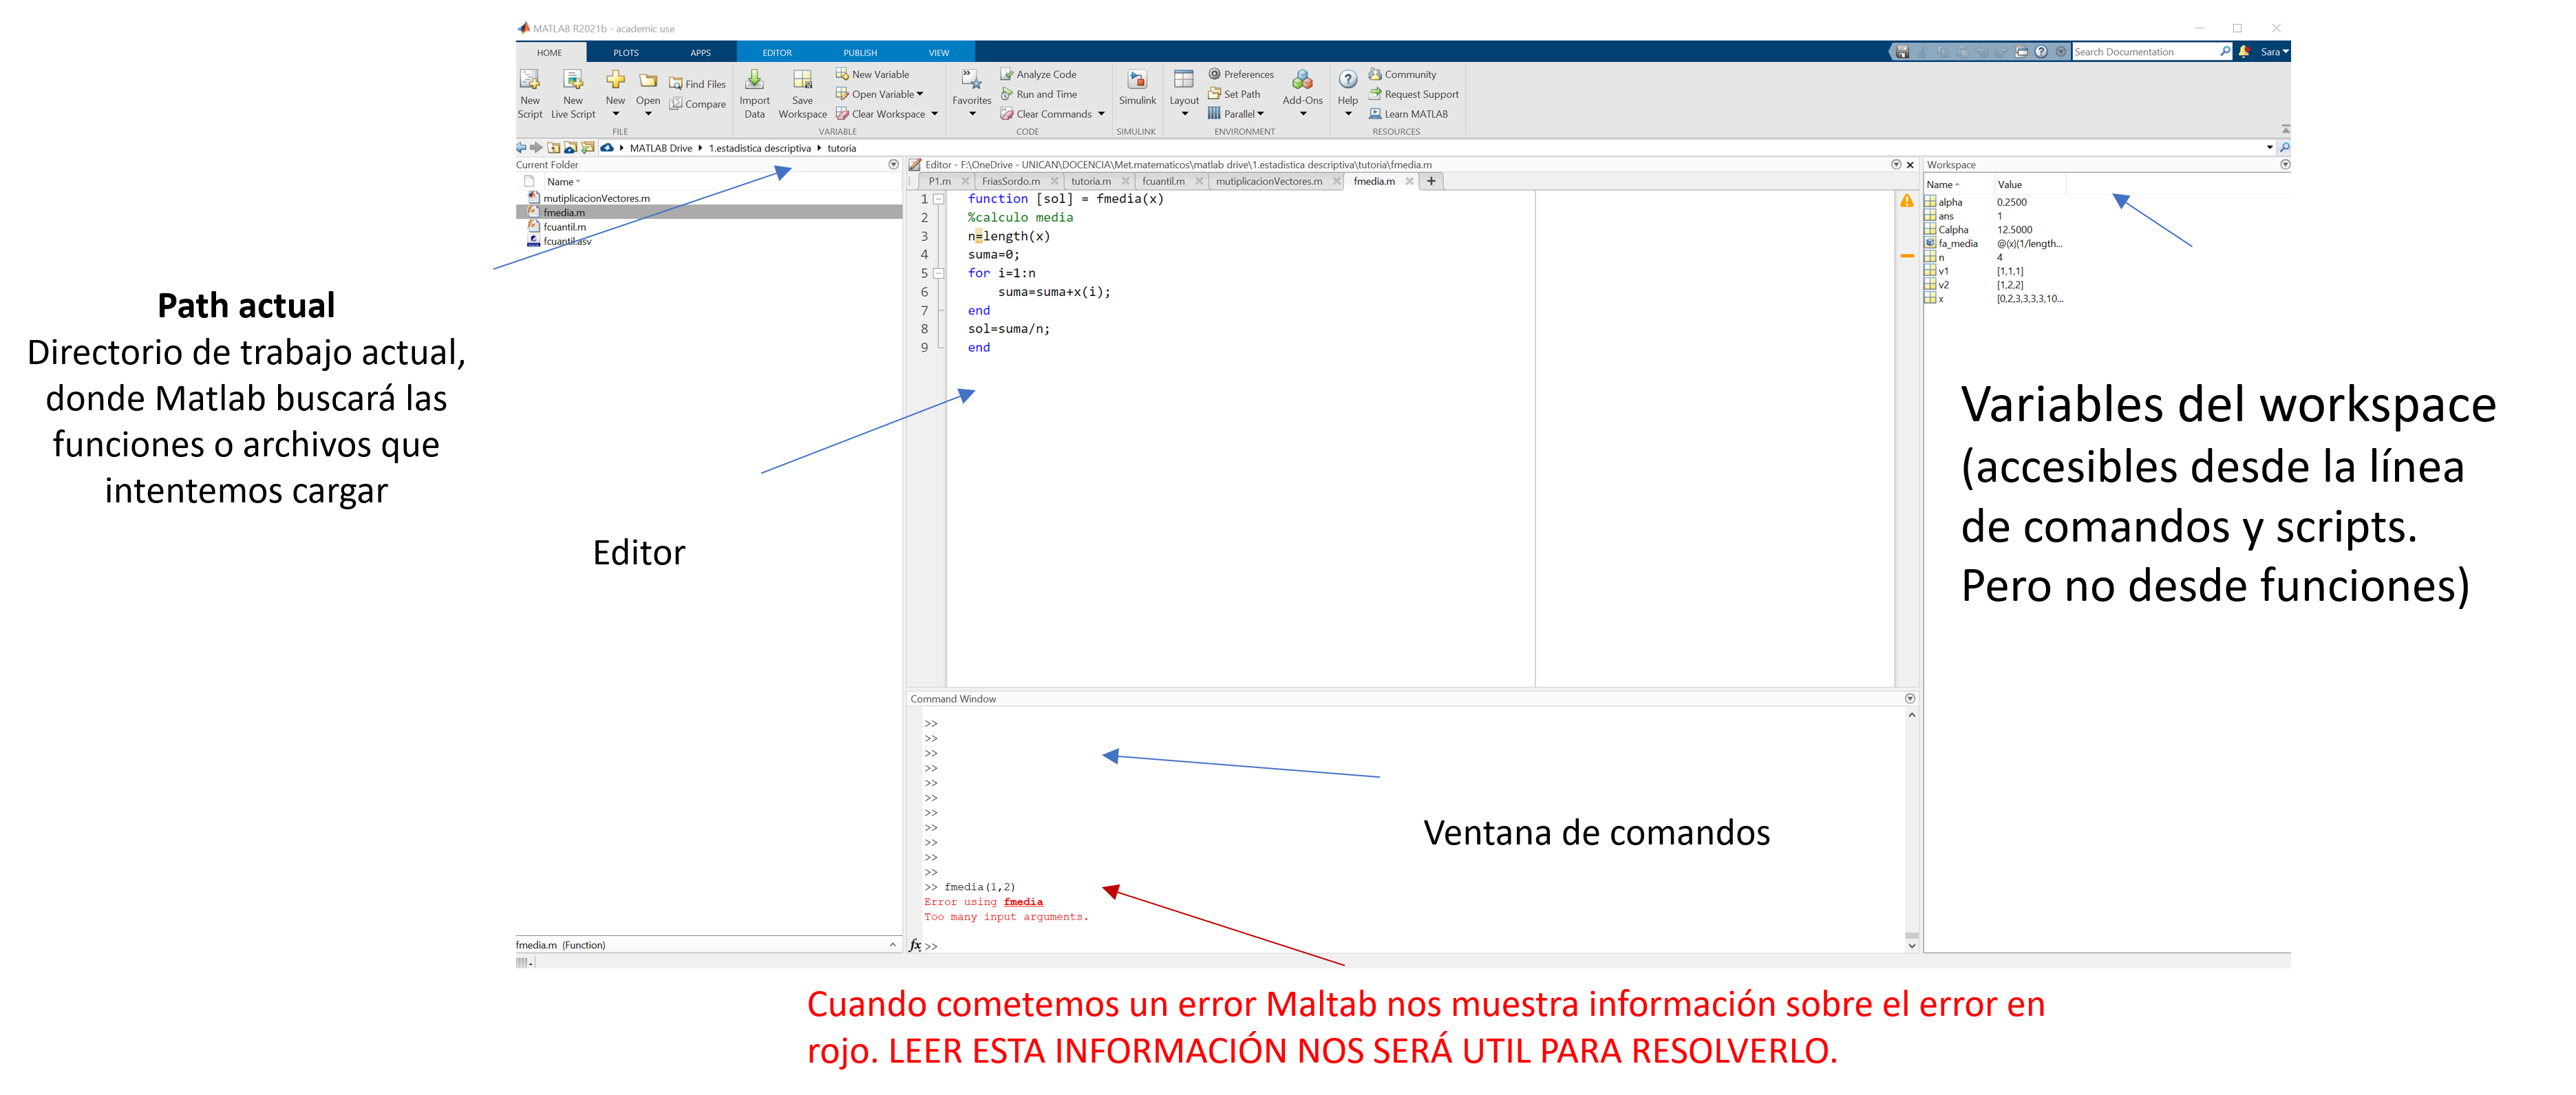

Si al abrir MATLAB no tiene un aspecto similar al de la imagen puede que tengas seleccionado otro layout. Para poner el layout o disposión de los elementos por defecto Seleccion Layout->Default en la pestaña Home.

**Introducción**

El nombre de MATLAB es un acrónimo de MATrix LABoratory. Hoy en día MATLAB es un programa muy potente con un entorno agradable, que incluye herramientas de visualización gráfica, así como un lenguaje de alto nivel. La interfaz principal de MATLAB se divide en varias partes:

- Las órdenes a ejecutar se escriben en el *Command Window* (ventana de comandos).

- En el editor (ventana *Editor*) es donde escribimos código que guardaremos en scripts (con extensión *.m) *o live scripts (extensión *.mlx*), para su posterior ejecución desde el *Command Window*. El color que aparece en la barra lateral a la derecha del script nos indica si la sintáxis es correcta (verde), es correcta pero podría llegar a dar problemas (naranja) o es incorrecta (rojo). Los comentarios (texto no ejecutable) se introducen con el caracter "*%".*

- La ventana *Workspace *(espacio de trabajo) proporciona información sobre las variables que están almacenadas en memoria.

Hay ciertas reglas para definir variables en MATLAB:

- Su nombre puede tener como máximo 63 caracteres que pueden ser letras, números y el guión bajo.

- El primer carácter tiene que ser una letra: *matriz2* es un nombre válido, *2matriz* no lo es.

- Las mayúsculas y las minúsculas tienen valor distintivo: la variable *X* es distinta de la variable *x*.

- No puede haber espacios en blanco: *modulo1 *es un nombre de variable válido, *modulo 1* no.

- Existen nombres que deben evitarse porque tienen significado propio en MATLAB: *ans*, *pi*, *Inf*, *i*, . . .

A tener en cuenta:

- Si se escribe el caracter "*;"* al final de una linea de código, dicha línea es ejecutada, pero el resultado de la ejecución no se muestra por pantalla.

- Los comandos *help, doc y lookfor* sirven para obtener ayuda sobre el resto de comandos/funciones. La documentación online de MATLAB (accesible mediante *doc*) es realmente buena.

help diag

 diag - Create diagonal matrix or get diagonal elements of matrix
    This MATLAB function returns a square diagonal matrix with the elements
    of vector v on the main diagonal.

    Syntax
      D = diag(v)
      D = diag(v,k)

      x = diag(A)
      x = diag(A,k)

    Input Arguments
      v - Diagonal elements
        vector
      A - Input matrix
        matrix
      k - Diagonal number
        integer

    Examples
      Create Diagonal Matrices
      Get Diagonal Elements



lookfor diagonal

balance                        - Diagonal scaling to improve eigenvalue accuracy
blkdiag                        - Block diagonal matrix
cdf2rdf                        - Convert complex diagonal form to real block diagonal form
diag                           - Create diagonal matrix or get diagonal elements of matrix
isdiag                         - Determine if matrix is diagonal
spdiags                        - Extract nonzero diagonals and create sparse band and diagonal matrices
double.trace    

**Operaciones básicas**

La forma de operar con MATLAB es igual que con una calculadora de bolsillo, usando los símbolos *+, -, *, /, ^*. Por ejemplo:

- Suma y resta:

2+4

ans = 6

2-4

ans = -2

- Multiplicación y división:

2*pi

ans = 6.2832

pi/10

ans = 0.3142

- Potenciación:

3^2

ans = 9

- Otros operadores importantes:

sqrt(4)  % raíz cuadrada

ans = 2

log(1)  % logaritmo neperiano

ans = 0

exp(1)  % exponencial

ans = 2.7183

sin(pi/2)  % seno

ans = 1

cos(pi/2)  % coseno

ans = 6.1232e-17

tan(pi/2)  % tangente

ans = 1.6331e+16

- Formatos:

format short  % o simplemente "format": 4 cifras decimales
1/3

ans = 0.3333

format long  % 15 cifras decimales
1/3

ans =    0.333333333333333


format rat  % formato racional
1/3

ans =        1/3     


format  % volvemos al formato corto de 4 cifras decimales

** Creación de vectores y matrices**

Hay varias maneras de crear un vector fila:

a = [1 4 9]

a =      1     4     9


a = [1, 4, 9]  % podemos dejar un espacio en blanco entre números o poner una coma

a =      1     4     9


a = 1:2:10  % secuencia regular de elementos entre 1 y 10, escogidos de 2 en 2

a =      1     3     5     7     9


Para crear un vector columna:

b = [-1; 2; 3]

b =     -1
     2
     3


b = [1 2 3]'  % la comilla simple se utiliza para transponer

b =      1
     2
     3


Para crear una matriz combinamos la definición de vector fila y vector columna. Por ejemplo:

M = [1 2 3; 4 5 6]  % matriz de 2 filas y 3 columnas

M =      1     2     3
     4     5     6


A = [1 2 1; 2 4 3; 3 5 2]  % matriz de 3 filas y 3 columnas

A =      1     2     1
     2     4     3
     3     5     2


Se pueden seleccionar elementos de una matriz indicando, entre paréntesis, la posición de la fila y la columna.

A(1, 3)  % elemento de la primera fila y tercera columna

ans = 1

Para extraer filas o columnas enteras se utiliza el símbolo "*:"*

A(2, :)  % fila 2

ans =      2     4     3


A(:, 1)  % columna 1

ans =      1
     2
     3


A(:, 1:3) % columnas 1, 2 y 3

ans =      1     2     1
     2     4     3
     3     5     2


A(:, [1, 3]) % columnas 1 y 3

ans =      1     1
     2     3
     3     2


Para crear una matriz de ceros:

mceros = zeros(2,3)  % matriz con 2 filas y 3 columnas de ceros

mceros =      0     0     0
     0     0     0


Para crear una matriz de unos:

munos = ones(2,3)  % matriz con 2 filas y 3 columnas de unos

munos =      1     1     1
     1     1     1


Para crear la matriz identidad:

I5 = eye(5)  % matriz identidad de orden 5

I5 =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


Para crear una matriz de números aleatorios:

maleatoria = rand(3,3)  % matriz 3x3 de números aleatorios (entre el 0 y el 1) 

maleatoria =     0.7922    0.0357    0.6787
    0.9595    0.8491    0.7577
    0.6557    0.9340    0.7431


Para extraer la diagonal principal de una matriz:

d = diag(maleatoria)

d =     0.7922
    0.8491
    0.7431


Para transponer una matriz:

M'  % transpuesta de M

ans =      1     4
     2     5
     3     6


Para saber cuál es el tamaño de una matriz:

size(M)  % tamaño (filas x columnas) de M

ans =      2     3


En el caso de un vector, podemos comprobar su longitud con *length*:

v = [5 6 -5 1 0];
length(v)  % número de elementos en un vector fila

ans = 5

Sean $A$ y $B$ dos matrices tales que:

A = [3 -2 1; 4 -8 -1; -5 2 2]

A =      3    -2     1
     4    -8    -1
    -5     2     2


B = [1 -1 0; -2 2 6; 7 -2 -1]

B =      1    -1     0
    -2     2     6
     7    -2    -1


Es importante saber que $A*B$ no es lo mismo que $A.*B$:

A*B  % producto matricial

ans =     14    -9   -13
    13   -18   -47
     5     5    10


A.*B  % producto elemento a elemento

ans =      3     2     0
    -8   -16    -6
   -35    -4    -2


**Cálculo del determinante de una matriz**

det(A)   % determinante de la matriz A

ans = -68

**Cálculo de la traza de una matriz**

trace(A)

ans = -3

#### Concatenación de matrices

Podemos definir una matriz concatenando dos o más matrices. 

El siguiente ejemplo concatena el vector v=[ 1 2 3] a la derecha de la matriz identidad de orden 3, guardando el resultado en la matriz B. Para poder concatenar a la derecha de la matriz identidad una matriz/vector este deberá tener dimensiones adecuadas (3 filas).

v=[1 2 3]

v =      1     2     3


B=[eye(3) v']%concatenamos un vector columna

B =      1     0     0     1
     0     1     0     2
     0     0     1     3


Ahora concatenaremos debajo de la matriz B el siguiente vector w=[1 2 3 4]. Para concatenar "debajo" indicaremos con ";" el salto de fila. La matriz resultante la guardaremos en C.

w=[1 2 3 4]%fector fila

w =      1     2     3     4


C=[B ; w] %concatenamos el vector fila w

C =      1     0     0     1
     0     1     0     2
     0     0     1     3
     1     2     3     4


#### Ejercicios propuestos

**Ejercicio 1: **

Crea las siguientes matrices:

- Matriz $4\times4$ con todos sus elementos cero

- Matriz $4\times4$ con todos sus elementos iguales a $0.5$

- Matriz $3\times5$ con todos sus elementos iguales a $\pi$

**Ejercicio 2:**

Sea la matriz $A=\left\lbrack \begin{array}{cccc}
1 & 3 & 2 & -1\\
0 & 0 & 2 & 5\\
-2 & 0 & 0 & 3\\
1 & 1 & 1 & -1
\end{array}\right\rbrack$

- Calcula la traza y el determinan

- Sustituye el elemento $a_{23}$ por un $-3$ y el $a_{12}$ por un $7$, y llama $$B$$ a la matriz resultante

- Extrae en un vector la primera fila de $$B$$, y en otro vector la segunda columna de $$B$$

- Extrae en una matriz $C$ las filas $1$ y $3$ de $B$ y en otra matriz $D$ las columnas $2$ y $4$

- Añade la matriz identidad $4\times4$ ($$I_{4\times4}$ $) a la derecha de $B$, y llama a la matriz resultante $B^*$. ¿Tienes algún problema?          

- Añade la matriz identidad $4\times4$ ($$I_{4\times4}$ $) debajo de $B$, y dale el nombre que quieras a la matriz resultante

- Crea un vector cuyos elementos sean los términos de la diagonal principal de $A$

- Crea una matriz 4x4 de números aleatorios entre $0$ y $1$ y súmasela a la matriz $A$

**Solución 1:**

Crea las siguientes matrices:

- Matriz $4\times4$ con todos sus elementos cero

zeros(4,4)

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


- Matriz $4\times4$ con todos sus elementos iguales a $0.5$

zeros(4,4)+0.5  % primera opción

ans =     0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000


ones(4,4)*0.5  % segunda opción

ans =     0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000    0.5000    0.5000


- Matriz $3\times5$ con todos sus elementos iguales a $\pi$

zeros(3,5)+pi  % primera opción

ans =     3.1416    3.1416    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416    3.1416    3.1416


ones(3,5)*pi  % segunda opción

ans =     3.1416    3.1416    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416    3.1416    3.1416
    3.1416    3.1416    3.1416    3.1416    3.1416


**Solución 2:**

Sea la matriz $A=\left\lbrack \begin{array}{cccc}
1 & 3 & 2 & -1\\
0 & 0 & 2 & 5\\
-2 & 0 & 0 & 3\\
1 & 1 & 1 & -1
\end{array}\right\rbrack$

- Sustituye el elemento $a_{23}$ por un $-3$ y el $a_{12}$ por un $7$, y llama $$B$$ a la matriz resultante

A = [1 3 2 -1; 0 0 2 5; -2 0 0 3; 1 1 1 -1];   % defino la matriz A
A(2,3) = -3; A(1,2) = 7; B = A

B =      1     7     2    -1
     0     0    -3     5
    -2     0     0     3
     1     1     1    -1


- Extrae en un vector la primera fila de $$B$$, y en otro vector la segunda columna de $$B$$

B(1, :)  % primera fila de B

ans =      1     7     2    -1


B(:, 2)  % segunda columna de B

ans =      7
     0
     0
     1


- Extrae en una matriz $C$ las filas $1$ y $3$ de $B$ y en otra matriz $D$ las columnas $2$ y $4$

C = B([1 3], :)  % filas 1 y 3 de B

C =      1     7     2    -1
    -2     0     0     3


D = B(:, [2 4])  % columnas 2 y 4 de B

D =      7    -1
     0     5
     0     3
     1    -1


- Añade la matriz identidad $4\times4$ ($$I_{4\times4}$ $) a la derecha de $B$, y llama a la matriz resultante $B^*$. ¿Tienes algún problema?

BB = [B, eye(4)]  % como el nombre de variable B* no esta permitido, 

BB =      1     7     2    -1     1     0     0     0
     0     0    -3     5     0     1     0     0
    -2     0     0     3     0     0     1     0
     1     1     1    -1     0     0     0     1


% llamo a esta nueva matriz BB

- Añade la matriz identidad $4\times4$ ($$I_{4\times4}$ $) debajo de $B$, y dale el nombre que quieras a la matriz resultante

BBB = [B; eye(4)]

BBB =      1     7     2    -1
     0     0    -3     5
    -2     0     0     3
     1     1     1    -1
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


- Crea un vector cuyos elementos sean los términos de la diagonal principal de $A$

v = diag(A)

v =      1
     0
     0
    -1


- Crea una matriz $4\times4$ de números aleatorios entre $0$ y $1$ y súmasela a la matriz $A$

A + rand(4,4)

ans =     1.3922    7.0318    2.8235   -0.9656
    0.6555    0.2769   -2.3052    5.4387
   -1.8288    0.0462    0.3171    3.3816
    1.7060    1.0971    1.9502   -0.2345
